# Notas de clase: Modelación experimental

## Clase 1: Presentación del curso

Mapa mental con las ideas de la clase.

## Tema: Objeto y método de la modelación experimental

### Clase 2: Objeto y método de la modelación experimental

### Clase 3: Objeto y método de la modelación experimental

### Clase 4: Objeto y método de la modelación experimental

#### Estructuras de modelos

**OE: **No se desea modelar la perturbación, se considera que ésta es un ruido que se adiciona a la salida. $\mathrm{nk}$ es el retardo puro del sistema.


$$\begin{array}{l}
y\left(t\right)=\frac{B\left(q\right)}{A\left(q\right)}u\left(t\right)+e\left(t\right)\\
A\left(q\right)=1+a_1 q^{-1} +\ldotp \ldotp \ldotp +a_{\mathrm{na}} q^{-\mathrm{na}} ,\;B\left(q\right)=\left(b_1 q^{-1} +\ldotp \ldotp \ldotp +b_{\mathrm{nb}} q^{-\mathrm{nb}} \right)q^{-\mathrm{nk}} ,\mathrm{nk}\ge 0
\end{array}$$


**ARX (auto-regresivo con variable exógena): **Es la estructura más común (se relaciona con el método de mínimos cuadrados), útil si se tiene una buena relación ruido/señal. La perturbación no se modela pero actúa por el canal de entrada del sistema. $\textrm{nk}$ es el retardo puro del sistema.


$$\begin{array}{l}
A\left(q\right)y\left(t\right)=B\left(q\right)u\left(t\right)+e\left(t\right)\\
A\left(q\right)=1+a_1 q^{-1} +\ldotp \ldotp \ldotp +a_{\mathrm{na}} q^{-\mathrm{na}} ,\;B\left(q\right)=\left(b_1 q^{-1} +\ldotp \ldotp \ldotp +b_{\mathrm{nb}} q^{-\mathrm{nb}} \right)q^{-\mathrm{nk}} ,\mathrm{nk}\ge 0
\end{array}$$


 **ARMAX (auto-regresivo, media móvil con variable exógena: **útil si la perturbación actúa por el canal de entrada (perturbaciones en la carga).


$$\begin{array}{l}
A\left(q\right)y\left(t\right)=B\left(q\right)u\left(t\right)+C\left(q\right)e\left(t\right)\\
C\left(q\right)=1+c_1 q^{-1} +\ldotp \ldotp \ldotp +c_{\mathrm{nc}} q^{-\mathrm{nc}} 
\end{array}$$


**Box-Jenkins: **


$$\begin{array}{l}
A\left(q\right)y\left(t\right)=B\left(q\right)u\left(t\right)+\frac{C\left(q\right)}{D\left(q\right)}e\left(t\right)\\
D\left(q\right)=1+d_1 q^{-1} +\ldotp \ldotp \ldotp +d_{\mathrm{nd}} q^{-\mathrm{nd}} \\

\end{array}$$


**Estructura general:**


$$\begin{array}{l}
F\left(q\right)y\left(t\right)=\frac{B\left(q\right)}{A\left(q\right)}u\left(t\right)+\frac{C\left(q\right)}{D\left(q\right)}e\left(t\right)\\
F\left(q\right)=1+f_1 q^{-1} +\ldotp \ldotp \ldotp +f_{\mathrm{nf}} q^{-\mathrm{nf}} \\

\end{array}$$


## Tema: Métodos no paramétricos de identificación

### Clase 5: Métodos no paramétricos de la respuesta temporal

#### Respuesta temporal para sistemas de primer orden

Una función de transferencia para un sistema de primer orden tiene la forma $G\left(s\right)=\frac{{\textrm{ae}}^{-\tau \mathrm{s}} }{s+b}=\frac{{\textrm{ke}}^{-\tau \mathrm{s}} }{\textrm{Ts}+1}$, siendo $k=\frac{a}{b},T=\frac{1}{b}$. Dicha función de transferencia corresponde entonces con la ecuación diferencial 


$$T\overset{\ldotp }{y} +y=\textrm{ku}\left(t-\tau \right)$$


cuya solución viene dada por


$$y=\textrm{Ak}\left(1-e^{-\frac{t-\tau }{T}} \right)u_s \left(t-\tau \right),{\;\;\;u}_s \left(t-\tau \right)=\left\lbrace \begin{array}{ll}
1 & t\ge \tau \\
0 & \textrm{en}\;\textrm{otro}\;\textrm{caso}
\end{array}\right.$$


para el caso de una entrada escalón con amplitud $A$, $u_A \left(t-\tau \right)=\left\lbrace \begin{array}{ll}
A & t\ge \tau \\
0 & \textrm{en}\;\textrm{otro}\;\textrm{caso}
\end{array}\right.$. 

En dicho contexto, es posible dar a los parámetros de la función de transferencia una interpretación acorde con la forma de la solución de la ecuación diferencial:

- $T-$ constante de tiempo del sistema: se deduce haciendo $t-\tau =T$, en cuyo caso $y\simeq 0\ldotp 632\textrm{Ak}$. De forma tal, $T$ es el tiempo que tarda el sistema en ir de su valor inicial al $63\ldotp 2%$ de su valor final (de estabilización).

- $k-$ ganancia del sistema: se deduce calculando el $\lim_{t\longrightarrow \infty } y\left(t\right)=\textrm{Ak}$. De forma tal, $k$ determina la amplificación con la que el sistema responde a la entrada.

- $\tau -$ retardo puro del sistema

- $A-$ amplitud de la entrada escalón aplicada al sistema

**Ejemplo: comparación de sistemas de primer orden**

¿Qué podría decirse de los siguientes sistemas de primer orden?


$$G_1 \left(s\right)=\frac{0\ldotp 5}{s+0\ldotp 25}=\frac{2}{4s+1},\;G_2 \left(s\right)=\frac{2}{s+4}=\frac{0\ldotp 5}{0\ldotp 25s+1}$$


Comparando en MatLab: con la función [tf](https://www.mathworks.com/help/control/ref/tf.html) podemos crear funciones de transferencia especificando los coeficientes del polinimio del numerador y del denominador.

clear;clc;close all
tf1=tf([0.5],[1 0.25])

tf1 =
 
    0.5
  --------
  s + 0.25
 
Continuous-time transfer function.



tf2=tf(2,[1 4])

tf2 =
 
    2
  -----
  s + 4
 
Continuous-time transfer function.



Con la función [step](https://www.mathworks.com/help/control/ref/lti.step.html) podemos graficar rápidamente la respuesta del sistema a una entrada de tipo escalón unitario.

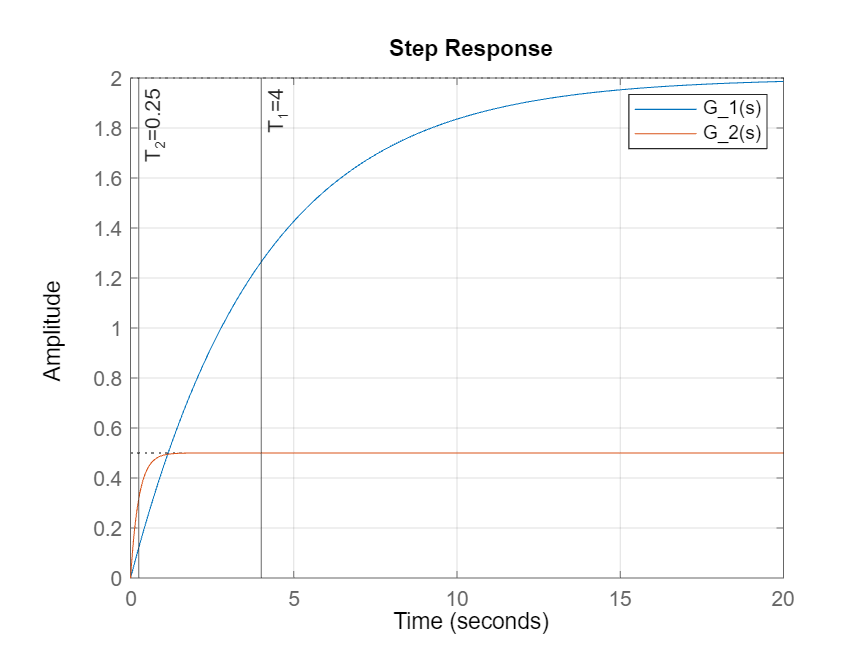

figure(1)
clf
step(tf1,20)
hold on
step(tf2,20)
grid on
xline([4,0.25],'-',{'T_1=4','T_2=0.25'})
legend({'G_1(s)','G_2(s)'})

En conclusión, el primer sistema crece más lento pero se estabiliza en un mayor valor mientras que el segundo crece más rápido y se estabiliza en un menor valor.

#### Ajuste mediante modelos de primer orden

**Método visual: **Los valores de los 3 parámetros se deducen de la gráfica

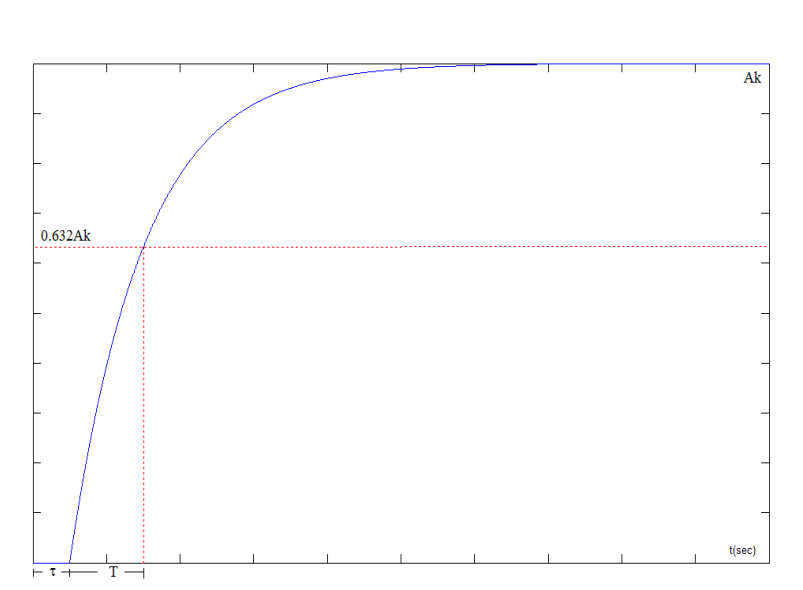

**Método de regresión lineal: **Los valores de los 3 parámetros se deducen mediante regresión. Se parte de la estructura $y=\textrm{Ak}\left(1-e^{-\frac{t-\tau }{T}} \right)$ y se deduce que $\ln \left(1-\frac{y}{\textrm{Ak}}\right)=-\frac{t}{T}+\frac{\tau }{T}$, o visto de otra forma, el problema se ha llevado a la forma $y=\textrm{at}+b,T=-\frac{1}{a},\tau =-\frac{b}{a}$. El valor de $k$ se calcula fácilmente como $k=\frac{\Delta y}{\Delta u}=\frac{y_0 -y_{\textrm{ss}} }{u_0 -u_A }$.

**Ejemplo:**

Se genera un modelo de segundo orden especificando los ceros, polos, ganancia y retardo del sistema mediante la función [zpk](https://www.mathworks.com/help/control/ref/zpk.html). El sistema que elegimos para el ejemplo no tiene ceros, tiene dos polos (-1.8 y -2.2), tiene una ganancia de 1.24 y un retardo de 0.89 segundos.

%creación de un modelo de segundo orden
G=zpk([],[-1.8 -2.2],1.24,'InputDelay',0.89)

G =
 
                      1.24
  exp(-0.89*s) * ---------------
                 (s+1.8) (s+2.2)
 
Continuous-time zero/pole/gain model.



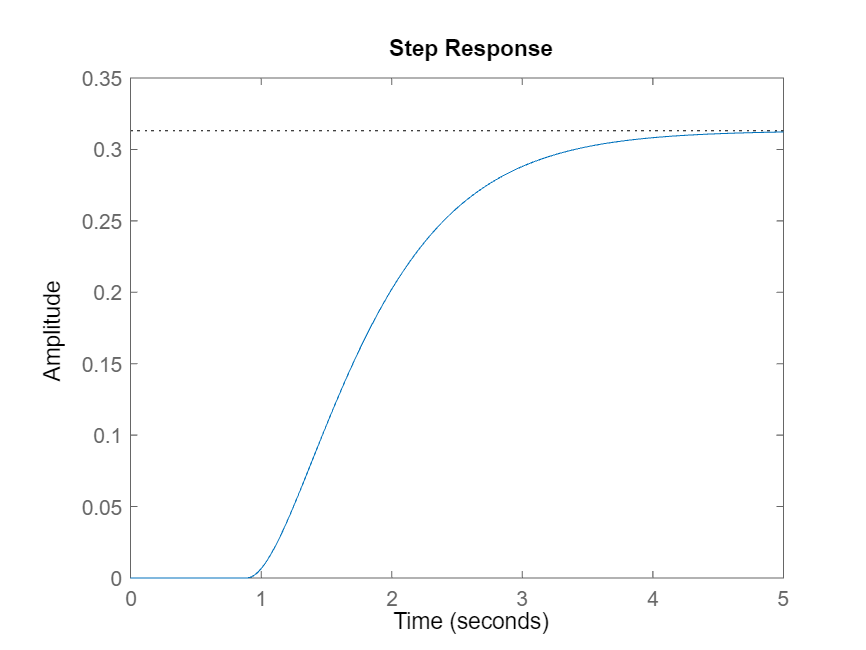

%generación de la respuesta temporal
figure(1)
clf
step(G);%comprobamos que el sistema se estabiliza

%[y,t]=step(G);%recolectamos los datos tal y como los arroja matlab
[y,t]=step(G,[0:0.01:6]);%recolectamos los datos a nuestro gusto
inicio=find(y>0,1)%identificamos el dato a partir del cual el modelo responde a la entrada

inicio = 91

yvals=y(inicio:end);%valores útiles de y
tvals=t(inicio:end);%valores útiles de t
k=yvals(end)-y(1);%valor de k según la fórmula

**Método de regresión**

[p,s]=polyfit(tvals,log(1-yvals/(k+eps)),1);%regresión lineal al logaritmo de y
T=-1/p(1);tau=-p(2)/p(1);%valores de parámetros  T y tau según las fórmulas
tf_est=tf(k,[T 1],'InputDelay',tau)%función de transferencia resultante

tf_est =
 
                    0.313
  exp(-1.44*s) * ------------
                 0.5551 s + 1
 
Continuous-time transfer function.



**Método gráfico**

tau2=t(inicio);%primer valor donde y reacciona a la entrada
valT=find(y>0.632*y(end),1);%posición donde y alcanza el 63.2% de su valor final
T2=t(valT)-tau2;%valor de T por definición
tf_est2=tf(k,[T2 1],'InputDelay',tau2)%función de transferencia resultante

tf_est2 =
 
                  0.313
  exp(-0.9*s) * ----------
                1.08 s + 1
 
Continuous-time transfer function.



**Comparación entre métodos**

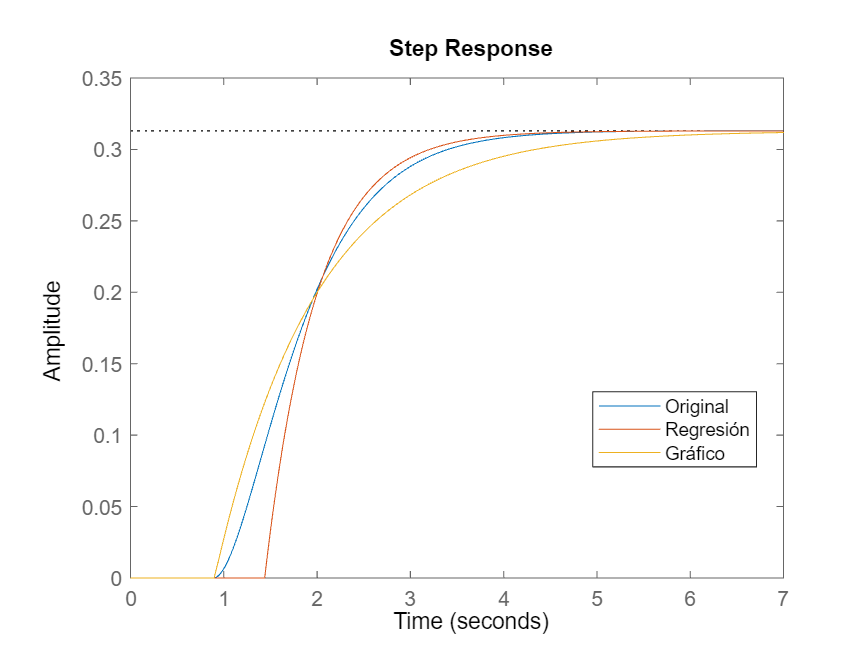

figure(1)
hold on
step(tf_est)
step(tf_est2)
legend({'Original','Regresión','Gráfico'},'Location','best')

#### Respuesta temporal para sistemas de segundo orden

Los sistemas de segundo orden son de la forma $G\left(s\right)=\frac{{\textrm{ae}}^{-\tau \mathrm{s}} }{s^2 +\textrm{bs}+c}=\frac{k\omega_0^2 e^{-\tau s} }{s^2 +2\zeta \omega_0 s+\omega_0^2 },\omega_0^2 =c,k=\frac{a}{c},\zeta =\frac{b}{2\sqrt{c}}$. Dicha función de transferencia se corresponde con la ecuación diferencial 


$$\overset{\ldotp \ldotp }{y} +2\zeta \omega_0 \overset{\ldotp }{y} +\omega_0 y=k\omega_0 u\left(t-\tau \right)$$


El caso que nos interesa en esta ecuación ocurre cuando $\zeta <1,{u\left(t-\tau \right)=u}_A \left(t-\tau \right)$. ya que las raíces del polinomio característico serán imaginarias y la solución de la ecuación diferencial vendría dada por

$y=\textrm{Ak}\left\lbrack 1-\frac{1}{\sqrt{1-\zeta^2 }}e^{-\zeta \omega_0 \left(t-\tau \right)} \textrm{sen}\left(\omega_1 \left(t-\tau \right)+\phi \right)\right\rbrack u_s \left(t-\tau \right),\omega_1 =\omega_0 \sqrt{1-\zeta^2 },\phi =\arccos \zeta$.

De forma similar al caso de la respuesta temporal en sistemas de primer orden, es posible dar interpretación a los parámetros del modelo de orden 2 como sigue

- $k-$ ganancia del sistema

- $\tau -$ retardo puro del sistema

- $\omega_0 -$ frecuencia natural (no amortiguada) del sistema

- $\omega_1 -$ frecuencia amortiguada del sistema

- $\zeta -$ razón de amortiguamiento

- $A-$ amplitud de la entrada escalón del sistema

Dependiendo de los valores de $\zeta$ tendremos 4 casos:

- $\zeta =0$, **sistema no amortiguado**

- $0<\zeta <1$, **sistema subamortiguado**

- $\zeta =1$, **sistema críticamente amortiguado**

- $\zeta >1$, **sistema sobreamortiguado**

a=4.3;
b=3.1;
c=5.1;
tau=1;
tf1=tf(a,[1 b c],'InputDelay',tau);%función de transferencia a partir de los datos
figure(1)
clf
step(tf1);

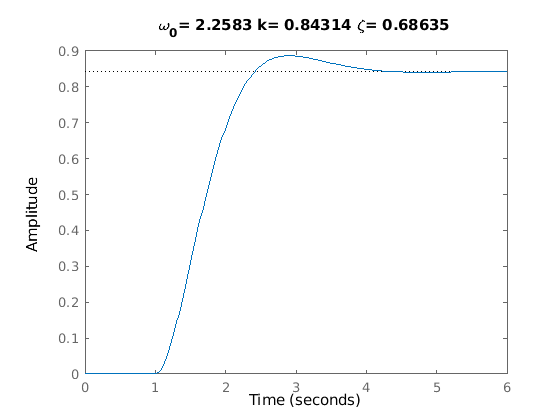

title(["\omega_0= "+sqrt(c)+" k= "+a/c+" \zeta= "+b/(2*sqrt(c))])%cálculo de valores de los parámetros

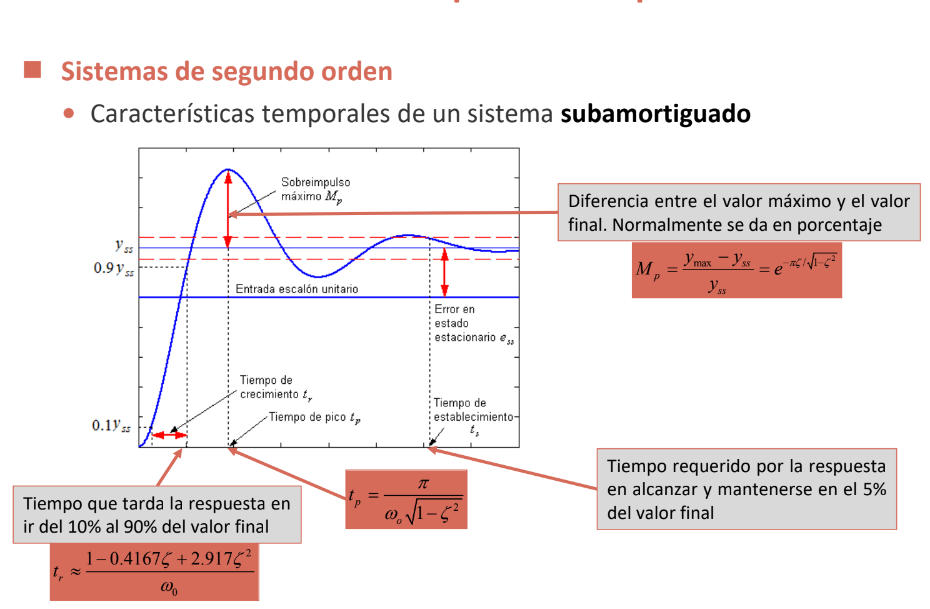

#### Ajuste mediante modelos de segundo orden

Para ajustar el modelo de segundo orden utilizamos un **método gráfico**. Para tal fin, determinamos 4 valores: el retardo del modelo $\tau$, el valor final del modelo $\Delta y$, el sobreimpulso máximo $M_p =e^{-\pi \frac{\zeta }{\sqrt{1-\zeta^2 }}} \Longrightarrow \zeta =\frac{1}{\sqrt{1+\frac{\pi^2 }{\ln^2 \left(\frac{M_p }{\Delta y}\right)}}}$ y el tiempo de pico $t_p =\frac{\pi }{\omega_0 \sqrt{1-\zeta^2 }}\Longrightarrow \omega_0 =\frac{\pi }{t_p \sqrt{1-\zeta^2 }}$

[y,t]=step(tf1);%recolección de datos por recomendación de MatLab
inicio=find(y>0,1);%dato a partir del cual el sistema reacciona
tau=t(inicio)%tiempo a partir del cual el sistema reacciona

tau = 1.0102

deltaY=y(end)-y(1)%delta de y por definición

deltaY = 0.8412

Mp=max(y)-y(end);%sobreimpulso máximo pode definición
Tp=t(y==max(y))-tau;%tiempo de pico, se le debe restar el retardo
%zeta=1/sqrt(1+(pi/log(Mp/deltaY))^2)%valor de z (diapositivas)
zeta=-log(Mp)/sqrt(pi^2+log(Mp)^2)%valor de z (Soderstrom)

zeta = 0.7015

omega0=pi/(Tp*sqrt(1-zeta^2))%valor de omega0 por fórmulas

omega0 = 2.3184

tf_est=tf(deltaY*omega0^2,[1 2*zeta*omega0 omega0^2],'InputDelay',tau)%función de transferencia estimada

tf_est =
 
                         4.522
  exp(-1.01*s) * ---------------------
                 s^2 + 3.253 s + 5.375
 
Continuous-time transfer function.



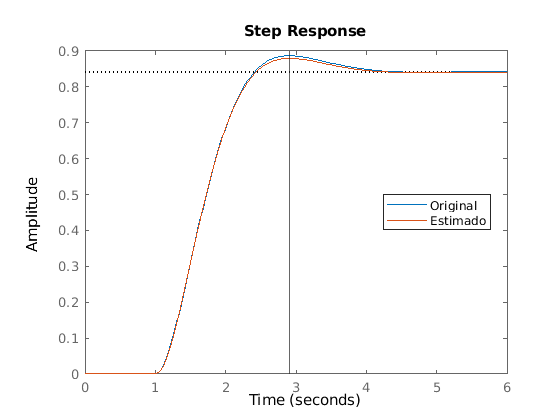

figure(2)
clf
step(tf1)
hold on
step(tf_est)
xline(Tp+tau)
legend({'Original','Estimado'},'Location','best')

#### Resumen de los métodos de respuesta temporal

- Se identifica si el sistema presenta oscilaciones o no. A los modelos que oscilan los aproximaremos por un sistema de orden 2, todos los demás modelos serán aproximados por un modelo de orden 1.

- Seleccionar el método para identificar parámetros: gráfico o de regresión.

- Implementar las fórmulas para identificar los valores de parámetros.

- Validar los resultados de la función de transferencia estimada versus la curva original.

### Clase 6: Método no paramétrico de la correlación

#### Estimación de la secuencia de ponderación mediante correlación


$$\hat{g} \left(\tau \right)=\frac{R_{\textrm{yu}} \left(\tau \right)}{R_u \left(0\right)}\approx \frac{\frac{1}{N}\sum_{t=\tau }^{N-1} y\left(t\right)u\left(t-\tau \right)}{\frac{1}{N}\sum_{t=0}^{N-1} u^2 \left(t\right)},\tau =0,1,\ldotp \ldotp \ldotp ,N-1,\;\;\hat{g} \left(\tau \right)=0\;\textrm{si}\;\tau \ge N$$


clear;clc;close all
N=1950;%número de muestras
M=10;%Longitud secuencia de ponderación
noise=0.1;%amplitud del ruido
num=[1];%numerador de la tf
den=[1 0.5];%denominador de la tf
 
tf1=tf(num,den,1)%función de transferencia objetivo

tf1 =
 
     1
  -------
  z + 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.



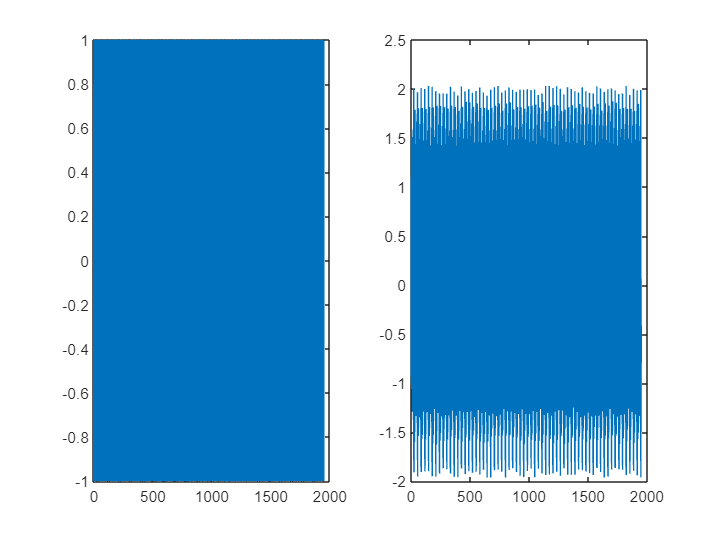

u=2*(prbs(5,N,[1 0 1 0 0])-0.5);%señal prbs de N datos con valores entre -1 y 1
xdata=0:1:N-1;%instantes de muestreo
[y,t]=lsim(tf1,u,xdata);%simulación del modelo con la entrada diseñada
y=y+noise*rand(length(y),1);%adición del ruido a la entrada
figure(1)
clf
subplot(1,2,1), plot(t,u)%gráfica de la entrada
subplot(1,2,2), plot(t,y)%fráfica de la salida

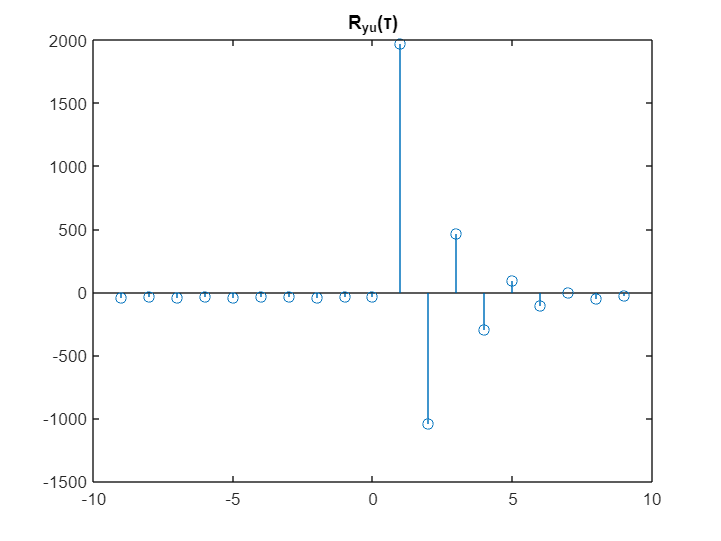

[cyu,lagsyu] = xcorr(y,u,M-1);%M elementos de la correlación entre y y u
[cu,lagsu] = xcorr(u,0);%correlación de la entrada con ella misma en el instante 0
tf_est=cyu(lagsyu>=0)./(N:-1:N-M+1)'/(cu/N);%fórmula para la secuencia de ponderación
delay=length(den)-length(num);%cálculo del retardo del sistema
tf_real=ldiv([1],[1 0.5],M-delay);%cálculo de la secuencia de ponderación
tf_real=[zeros(1,delay) tf_real];%adición del retardo a la secuencia de ponderación
figure(2)
clf
stem(lagsyu,cyu)%gráfica de la correlación de y y u
title('R_{yu}(\tau)')

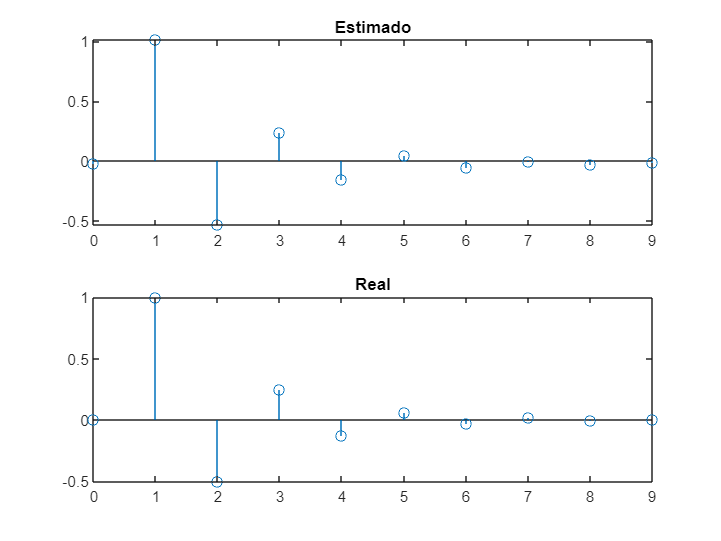

pdata=0:1:M-1;
figure(3)
clf
subplot(2,1,1)
stem(pdata,tf_est)%secuencia estimada
title('Estimado')
subplot(2,1,2)
stem(pdata,tf_real)%secuencia real
title('Real')

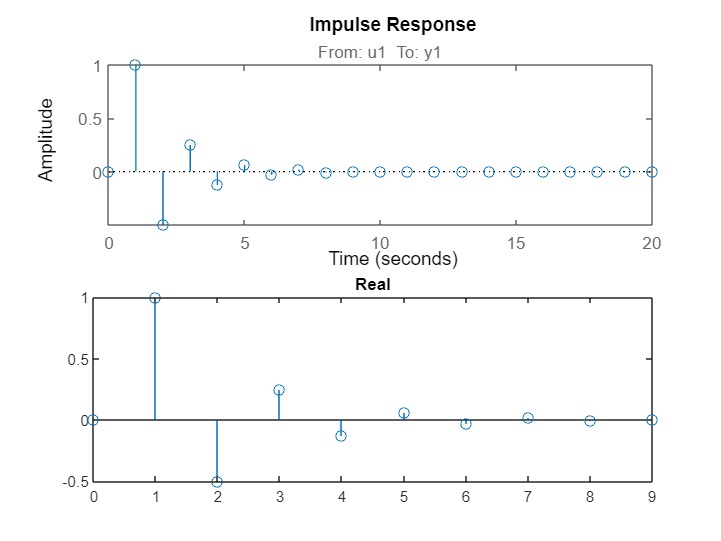

data = iddata(y,u');%datos para usar las funciones mejoradas de MatLab
sys = impulseest(data,M);%secuencia de ponderación estimada por MatLab
figure(4)
clf
subplot(2,1,1)
h = impulseplot(sys);%secuencia de ponderación estimada por MatLab
subplot(2,1,2)
stem(pdata,tf_real)%secuencia real
title('Real')

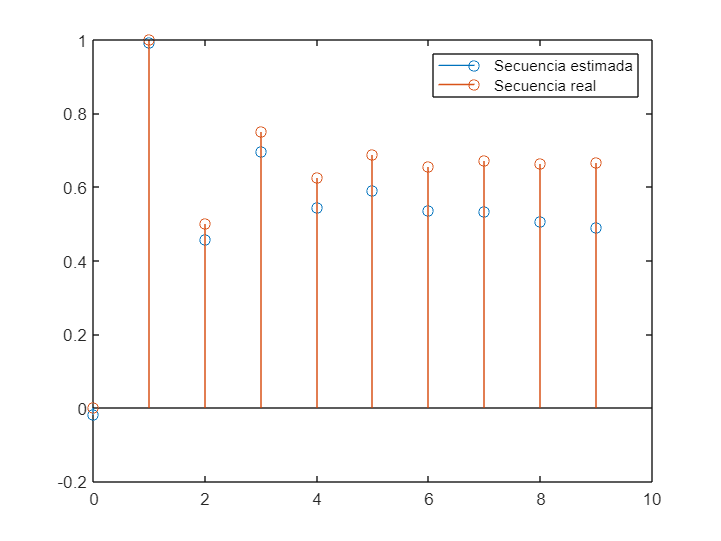

figure(5)
clf
response=cumsum(tf_est.*ones(length(tf_est),1));%convolución a la entrada de tipo escalón para la secuencia estimada
stem(pdata,response)
hold on
response2=cumsum(tf_real'.*ones(length(tf_est),1));%convolución a la entrada de tipo escalón para la secuencia real
stem(pdata,response2)
legend({'Secuencia estimada', 'Secuencia real'})

## Tema: Métodos paramétricos de identificación

### Clase 7: Método de mínimos cuadrados (teoría)

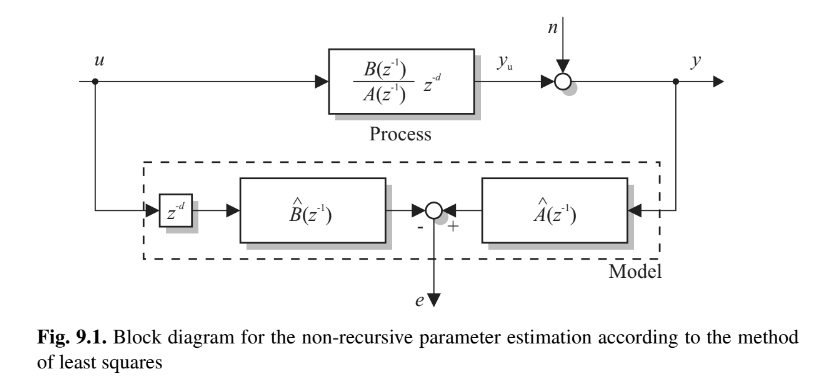

Partimos de un modelo cuya función de transferencia está dada por


$$G_p \left(z\right)=\frac{y_u \left(z\right)}{u\left(z\right)}=\frac{B\left(z\right)}{A\left(z\right)}=\frac{\left(b_1 z^{-1} +\ldotp \ldotp \ldotp +b_{\mathrm{nb}} z^{-\mathrm{nb}} \right)z^{-d} }{1+a_1 z^{-1} +\ldotp \ldotp \ldotp +a_{\mathrm{na}} z^{-\mathrm{na}} }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


Ahora bien, consideraremos que la señal de salida de nuestro sistema estará dada por la superposición de la salida del proceso $y_u \left(k\right)$ y una perturbación estocástica $n\left(k\right)$, es decir

$y\left(k\right)=y_u \left(k\right)+n\left(k\right)\;\;\;\;\;\;\;\;\;\;\;\left(2\right)$.

La tarea que nos proponemos entonces es determinar los parámetros desconocidos $a_i ,b_i$ tras la recolección de $N$ datos de la entrada $u\left(k\right)$ y la salida $y\left(k\right)$ del sistema, sujeta a las siguientes suposiciones:

- El proceso se encuentra en estado estacionario para $k<0$.

- El orden $\mathrm{na}$ y retardo $\mathrm{nk}$ del modelo son conocidos exáctamente (la determinación del orden y retardo apropiados se verá más adelante).

- La entrada $u\left(k\right)$ es conocida con precisión.

- La perturbación $n\left(k\right)$ es estacionaria y $E\left\lbrace n\left(k\right)\right\rbrace =0$.

Podemos transformar (1)  al dominio del tiempo para obtener la ecuación en diferencias


$$y_u \left(k\right)+a_1 y_u \left(k-1\right)+\ldotp \ldotp \ldotp +a_m y_u \left(k-\mathrm{na}\right)=b_1 u\left(k-d-1\right)+\ldotp \ldotp \ldotp +b_{\mathrm{nb}} u\left(k-d-\mathrm{nb}\right)\;\;\;\;\;\;\;\;\;\left(3\right)$$


Adicionalmente, podemos interpretar que (3) es una prediccón de $y\left(k\right)$ basada en las mediciones obtenidas hasta el instante anterior, es decir


$$\hat{y} \left(k|k-1\right)=-\hat{a_1 } \left(k-1\right)y\left(k-1\right)-\ldotp \ldotp \ldotp -\hat{a_m } \left(k-1\right)y\left(k-\mathrm{na}\right)+\hat{b_1 } \left(k-1\right)u\left(k-d-1\right)+\ldotp \ldotp \ldotp +\hat{b_{\mathrm{nb}} } u\left(k-d-\mathrm{nb}\right)=\phi^T \left(k\right)\hat{\theta} \left(k-1\right)$$


donde


$$\begin{array}{l}
\phi^T \left(k\right)=\left(-y\left(k-1\right),\ldotp \ldotp \ldotp ,-y\left(k-\mathrm{na}\right)|u\left(k-d-1\right),\ldotp \ldotp \ldotp ,u\left(k-d-\mathrm{nb}\right)\right)\\
\hat{\theta^T } =\left(\hat{a_1 } ,\ldotp \ldotp \ldotp ,\hat{a_{\mathrm{na}} } |\hat{b_1 } ,\ldotp \ldotp \ldotp ,\hat{b_{\mathrm{nb}} } \right)
\end{array}$$


Pero, por la definición de cada $y\left(k\right)$ tenemos que 


$$\begin{array}{l}
\hat{y} \left(k|k-1\right)=-\hat{a_1 } \left(k-1\right)\left(y_u \left(k-1\right)+n\left(k-1\right)\right)-\ldotp \ldotp \ldotp -\hat{a_m } \left(k-1\right)\left(y_u \left(k-\mathrm{na}\right)+n\left(k-\mathrm{na}\right)\right)+\hat{b_1 } \left(k-1\right)u\left(k-d-1\right)+\ldotp \ldotp \ldotp +\hat{b_{\mathrm{nb}} } u\left(k-d-\mathrm{nb}\right)\\
=\underset{\mathrm{Componente}\;\mathrm{determinista}\;\mathrm{de}\;\mathrm{la}\;\mathrm{señal}}{\underbrace{-\hat{a_1 } \left(k-1\right)y_u \left(k-1\right)-\ldotp \ldotp \ldotp -\hat{a_m } \left(k-1\right)y_u \left(k-\mathrm{na}\right)+\hat{b_1 } \left(k-1\right)u\left(k-d-1\right)+\ldotp \ldotp \ldotp +\hat{b_{\mathrm{nb}} } u\left(k-d-\mathrm{nb}\right)} } \underset{\mathrm{Componente}\;\mathrm{estocástico}\;\mathrm{de}\;\mathrm{la}\;\mathrm{señal}}{\underbrace{-\hat{a_1 } \left(k-1\right)n\left(k-1\right)-\ldotp \ldotp \ldotp -\hat{a_m } \left(k-1\right)n\left(k-\mathrm{na}\right)} } \\
=\phi_u^T \left(k\right)\hat{\theta} \left(k-1\right)+\phi_n^T \left(k\right)\hat{\theta} \left(k-1\right)
\end{array}$$


Siendo


$$\begin{array}{l}
\phi_u^T \left(k\right)=\left(-y_u \left(k-1\right),\ldotp \ldotp \ldotp ,-y_u \left(k-\mathrm{na}\right)|u\left(k-d-1\right),\ldotp \ldotp \ldotp ,u\left(k-d-\mathrm{nb}\right)\right)\\
\phi_n^T \left(k\right)=\left(-n\left(k-1\right),\ldotp \ldotp \ldotp ,-n\left(k-\mathrm{na}\right)|\underset{\mathrm{nb}}{\underbrace{0,\ldotp \ldotp \ldotp ,0} } \right)
\end{array}$$


De esta forma, la diferencia entre las observaciones y las predicciones del modelo vendrían dadas por

$\underset{\mathrm{Nueva}\;\mathrm{observación}}{\underbrace{y\left(k\right)} } -\underset{\mathrm{Predicción}}{\underbrace{\hat{y} \left(k|k-1\right)} } =\phi_u^T \left(k\right)\theta +n\left(k\right)-\phi_u^T \left(k\right)\hat{\theta} \left(k-1\right)-\phi_n^T \left(k\right)\hat{\theta} \left(k-1\right)=\underset{\mathrm{Error}}{\underbrace{e\left(k\right)} }$.

Donde es de particular importancia el caso en el que $\hat{\theta} =\theta$ ya que la ecuación anterior se convierte en


$$\phi_u^T \left(k\right)\theta +n\left(k\right)-\phi_u^T \left(k\right)\theta -\phi_n^T \left(k\right)\theta =n\left(k\right)-\phi_n^T \left(k\right)\theta =n\left(k\right)+a_1 \left(k-1\right)n\left(k-1\right)+\ldotp \ldotp \ldotp +a_m \left(k-1\right)n\left(k-\mathrm{na}\right)=e\left(k\right)$$


Es posible llegar a este mismo resultado analizando el diagrama de estimación por mínimos cuadrados (Figura 9.1 de Isermann) como se sigue. $y\left(k\right)=y_u \left(k\right)+n\left(k\right)$ y tenemos que $y_u \left(k\right)=\frac{B\left(q\right)}{A\left(q\right)}u\left(k\right)$. Nótese que para obtener el error de predicción, el diagrama nos sugiere hacer $\hat{A\left(q\right)} y\left(k\right)-\hat{B\left(q\right)} u\left(k\right)={\hat{A\left(q\right)} y}_u \left(k\right)+\hat{A\left(q\right)} n\left(k\right)-\hat{B\left(q\right)u\left(k\right)} =\hat{A\left(q\right)} \frac{B\left(q\right)}{A\left(q\right)}u\left(k\right)+\hat{A\left(q\right)} n\left(k\right)-\hat{B\left(q\right)} u\left(k\right)=e\left(k\right)$. Tal y como en el caso anterior, $\hat{\theta} =\theta \Longrightarrow \hat{A\left(q\right)} =A\left(q\right)\wedge \hat{B\left(q\right)} =B\left(q\right)$, por tanto $A\left(q\right)y\left(k\right)-B\left(q\right)u\left(k\right)=A\left(q\right)n\left(k\right)=n\left(k\right)+a_1 \left(k-1\right)n\left(k-1\right)+\ldotp \ldotp \ldotp +a_m \left(k-1\right)n\left(k-\mathrm{na}\right)=e\left(k\right)$.

Estas últimas ecuaciones tendrán repercursiones fundamentales cuando estudiemos la convergencia de los parámetros a sus valores reales.

Ahora bien, para los análisis anteriores solo hemos utilizado un único valor para la predicción. En general, necesitaremos recopilar muchos más datos (como mínimo $Q=\max \left\lbrace \mathrm{na},\mathrm{nb}+d\right\rbrace$. Para simplificar cálculos en adelante, asumiremos que $\mathrm{na}=\mathrm{nb}=m$. Podemos plantear entonces el vector de observaciones 


$$Y\left(m+d+N\right)=\left(y\left(m+d\right),\ldotp \ldotp \ldotp ,y\left(m+d+N\right)\right)$$


y una matriz de predictores asociados


$$\begin{array}{l}
\Phi \left(m+d+N\right)=\left\lbrack \begin{array}{ccccccc}
-y\left(m+d-1\right) & \cdots  & -y\left(d\right) & | & u\left(m-1\right) & \cdots  & u\left(0\right)\\
-y\left(m+d\right) & \cdots  & -y\left(d+1\right) & | & u\left(m\right) & \cdots  & u\left(1\right)\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
-y\left(m+d+N-1\right) & \cdots  & -y\left(d+N\right) & | & u\left(m+N-1\right) & \cdots  & u\left(N\right)
\end{array}\right\rbrack \in M_{\left(N+1\right)\times 2m} \\
=\left\lbrack \begin{array}{c}
\phi^T \left(m+d\right)\\
\phi^T \left(m+d+1\right)\\
\vdots \\
\phi^T \left(m+d+N\right)
\end{array}\right\rbrack 
\end{array}$$


Para llegar al problema de regresión lineal dado por


$${\Phi \left(m+d+N\right)\theta =Y}^T \left(m+d+N\right)$$


que resumiremos de la forma $\Phi \theta =Y^T$. Este problema, en general, no tendrá solución, razón por la cual recurriremos a la pseudo-inversa para llegar al problema

$\Phi^T \Phi \theta =\Phi^T Y^T \Longrightarrow \theta ={\left(\Phi^T \Phi \right)}^{-1} \Phi^T Y^T$, $\Phi^T \Phi \in M_{2m\times 2m}$

Este problema podemos abordarlo desde la perspectiva de las funciones de costo o directamente desde el álgebra lineal. Para el caso de la función de costo, tenemos que minimizar


$$\begin{array}{l}
V\left(\hat{\theta} ,N+1\right)=\frac{1}{2}\sum_{k=m+d}^{N+m+d} {\left\lbrack y\left(k\right)-\phi^T \left(k\right)\hat{\theta} \right\rbrack }^2 =\frac{1}{2}\sum_{k=m+d}^{N+m+d} {e\left(k\right)}^2 =\frac{1}{2}E^T \left(m+d+N\right)E\left(m+d+N\right)\\
E^T \left(m+d+N\right)=\left(e\left(m+d\right),\cdots ,e\left(m+d+N\right)\right)\ldotp 
\end{array}$$


Notando que $E^T E={\left(Y-\Phi \hat{\theta} \right)}^T \left(Y-\Phi \hat{\theta} \right)$ se llega finalmente a que 

$\min_{\vartheta } \left\lbrace V\left(\vartheta ,N+1\right)\right\rbrace =\hat{\theta} \iff \left(\left(\Phi^T Y-\Phi^T \Phi \hat{\theta} =0\right)\wedge \left(\Phi^T \Phi \;\mathrm{es}\;\mathrm{positivo}\;\mathrm{definida}\right)\right)$.

Para el caso de la perspectiva del álgebra lineal, las deducciones son mucho más sencillas. Solo resta pedir que $\Phi \hat{\theta} ={\mathrm{proy}}_W Y$, siendo $W=C\left(\Phi \right)$ el espacio columna de $\Phi$. De esta forma, se sigue inmediatamente que $\Phi^T Y-\Phi^T \Phi \hat{\theta} =0$. Para el caso de la segunda condición basta con que $\mathrm{rank}\left(\Phi \right)=\dim \left\lbrace W\right\rbrace =2m$ puesto que $X^T \Phi^T \Phi X={\left(\Phi X\right)}^T \left(\Phi X\right)=\left(\Phi X\right)\cdot \left(\Phi X\right)$.

**El método de mínimos cuadrados no recursivo puede establecerse como:**

- Recopilar los datos del modelo (N+m+d).

- Construir las matrices $\Phi ,Y$.

- Determinar los elementos de $\Phi^T \Phi ,{\;\Phi }^T Y$.

- Resolver $\hat{\theta} ={\left(\Phi^T \Phi \right)}^{-1} \Phi^T Y$.

Es particularmente interesante estudiar los elementos que componen a $\Phi^T \Phi$ y a $\frac{\Phi^T \Phi }{N+1}$


$$\Phi^T \Phi =\left\lbrack \begin{array}{ccccccccc}
\sum_{k=m+d-1}^{m+d-1+N} y^2 \left(k\right) & \sum_{k=m+d-2}^{m+d-2+N} y\left(k\right)y\left(k-1\right) & \cdots  & \sum_{k=m+d-1}^{m+d-1+N} y\left(k\right)y\left(k-m+1\right) & | & -\sum_{k=m+d-1}^{m+d-1+N} y\left(k\right)u\left(k-d\right) & -\sum_{k=m+d-1}^{m+d-1+N} y\left(k\right)u\left(k-d-1\right) & \cdots  & -\sum_{k=m+d-1}^{m+d-1+N} y\left(k\right)u\left(k-d-m+1\right)\\
\sum_{k=m+d-2}^{m+d-2+N} y\left(k\right)y\left(k+1\right) & \sum_{k=m+d-2}^{m+d-2+N} y^2 \left(k\right) & \cdots  & \sum_{k=m+d-2}^{m+d-2+N} y\left(k\right)y\left(k-m+2\right) & | & -\sum_{k=m+d-2}^{m+d-2+N} y\left(k\right)u\left(k-d+1\right) & -\sum_{k=m+d-2}^{m+d-2+N} y\left(k\right)u\left(k-d\right) & \cdots  & -\sum_{k=m+d-2}^{m+d-2+N} y\left(k\right)u\left(k-d-m+2\right)\\
\vdots  & \vdots  & \cdots  & \vdots  & \vdots  & \vdots  & \vdots  & \cdots  & \vdots \\
\sum_{k=d}^{d+N} y\left(k\right)y\left(k+m-1\right) & \cdots  & \cdots  & \sum_{k=d}^{d+N} y^2 \left(k\right) & | & -\sum_{k=d}^{d+N} y\left(k\right)u\left(k-d+m-1\right) & \cdots  & \cdots  & -\sum_{k=d}^{d+N} y\left(k\right)u\left(k-d\right)\\
- & - & - & - & - & - & - & - & -\\
-\sum_{k=m-1}^{m-1+N} u\left(k\right)y\left(k+d\right) & -\sum_{k=m-1}^{m-1+N} u\left(k\right)y\left(k+d-1\right) & \cdots  & -\sum_{k=m-1}^{m-1+N} u\left(k\right)y\left(k+d-m+1\right) & | & \sum_{k=m-1}^{m-1+N} u^2 \left(k\right) & \sum_{k=m-1}^{m-1+N} u\left(k\right)u\left(k-1\right) & \cdots  & \sum_{k=m-1}^{m-1+N} u\left(k\right)u\left(k-m+1\right)\\
-\sum_{k=m-2}^{m-2+N} u\left(k\right)y\left(k+d+1\right) & -\sum_{k=m-2}^{m-2+N} u\left(k\right)y\left(k+d\right) & \cdots  & -\sum_{k=m-2}^{m-2+N} u\left(k\right)y\left(k+d-m+2\right) & | & \sum_{k=m-2}^{m-2+N} u\left(k\right)u\left(k+1\right) & \sum_{k=m-2}^{m-2+N} u^2 \left(k\right) & \cdots  & \sum_{k=m-2}^{m-2+N} u\left(k\right)u\left(k-m+2\right)\\
\vdots  & \vdots  & \cdots  & \vdots  & \vdots  & \vdots  & \vdots  & \cdots  & \vdots \\
-\sum_{k=0}^N u\left(k\right)y\left(k+d+m-1\right) & -\sum_{k=0}^N u\left(k\right)y\left(k+d+m-2\right) & \cdots  & -\sum_{k=0}^N u\left(k\right)y\left(k+d\right) & | & \sum_{k=0}^N u\left(k\right)u\left(k+m-1\right) & \vdots  & \cdots  & \sum_{k=0}^N u^2 \left(k\right)
\end{array}\right\rbrack$$



$$\frac{\Phi^T \Phi }{N+1}=\left\lbrack \begin{array}{ccccccccc}
\hat{R_{\mathrm{yy}} } \left(0\right) & \hat{R_{\mathrm{yy}} } \left(1\right) & \cdots  & \hat{R_{\mathrm{yy}} } \left(m-1\right) & | & \hat{{-R}_{\mathrm{yu}} } \left(d\right) & \hat{{-R}_{\mathrm{yu}} } \left(d+1\right) & \cdots  & \hat{{-R}_{\mathrm{yu}} } \left(d+m-1\right)\\
\hat{R_{\mathrm{yy}} } \left(-1\right) & \hat{R_{\mathrm{yy}} } \left(0\right) & \cdots  & \hat{R_{\mathrm{yy}} } \left(m-2\right) & | & \hat{{-R}_{\mathrm{yu}} } \left(d-1\right) & \cdots  & \cdots  & \hat{{-R}_{\mathrm{yu}} } \left(d+m-2\right)\\
\vdots  & \vdots  & \cdots  & \vdots  & \vdots  & \vdots  & \cdots  & \cdots  & \vdots \\
\hat{R_{\mathrm{yy}} } \left(-m+1\right) & \hat{R_{\mathrm{yy}} } \left(-m+2\right) & \cdots  & \hat{R_{\mathrm{yy}} } \left(0\right) & | & \hat{{-R}_{\mathrm{yu}} } \left(d-m+1\right) & \cdots  & \cdots  & \hat{{-R}_{\mathrm{yu}} } \left(d\right)\\
- & - & - & - & - & - & - & - & -\\
\hat{{-R}_{\mathrm{uy}} } \left(-d\right) & \hat{{-R}_{\mathrm{uy}} } \left(-d+1\right) & \cdots  & \hat{{-R}_{\mathrm{uy}} } \left(-d+m-1\right) & | & \hat{R_{\mathrm{uu}} } \left(0\right) & \cdots  &  & \hat{R_{\mathrm{uu}} } \left(m-1\right)\\
\hat{{-R}_{\mathrm{uy}} } \left(-d-1\right) & \cdots  & \cdots  & \hat{{-R}_{\mathrm{uy}} } \left(-d+m-2\right) & | & \vdots  & \ddots  &  & \\
\vdots  & \cdots  & \cdots  & \vdots  & \vdots  &  &  &  & \\
\hat{{-R}_{\mathrm{uy}} } \left(-d-m+1\right) & \cdots  & \cdots  & \hat{{-R}_{\mathrm{uy}} } \left(-d\right) & | & \hat{R_{\mathrm{uu}} } \left(-m+1\right) &  &  & \hat{R_{\mathrm{uu}} } \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
R_{\mathrm{yy}}  & | & {-R}_{\mathrm{yu}} \\
- & - & -\\
-R_{\mathrm{uy}}  & | & R_{\mathrm{uu}} 
\end{array}\right\rbrack$$


Nótese que $\hat{{-R}_{\mathrm{uy}} } \left(-d-1\right)=\hat{R_{\mathrm{yu}} } \left(d+1\right)$ y por lo tanto $R_{\mathrm{uy}} ={\left(-R_{\mathrm{yu}} \right)}^T$. De tal modo, podemos llamar de ahora en adelante $P=\Phi^T \Phi$ y $R=\frac{\Phi^T \Phi }{N+1}$.

Siguiendo la misma lógica del empleada anteriormente, resulta fácil ver que 

$\frac{\Phi^T Y}{N+1}=\left\lbrack \begin{array}{c}
-\hat{R_{\mathrm{yy}} } \left(1\right)\\
\vdots \\
-\hat{R_{\mathrm{yy}} } \left(m\right)\\
-\\
\hat{R_{\mathrm{uy}} } \left(d+1\right)\\
\vdots \\
\hat{R_{\mathrm{uy}} } \left(d+m\right)
\end{array}\right\rbrack$, y llamamos $B=\frac{\Phi^T Y}{N+1}$

Por tanto $\hat{\theta} =R^{-1} B$.

**Estudio de la convergencia a los parámetros reales en el método de mínimos cuadrados**

Nos preguntamos ahora por la esperanza de los parámetros estimados


$$\varepsilon \left\lbrace \hat{\theta} \right\rbrace =\varepsilon \left\lbrace {\left(\Phi^T \Phi \right)}^{-1} \Phi^T Y\right\rbrace$$


Recordando que $\underset{\mathrm{Nuevas}\;\mathrm{obervaciones}}{\underbrace{Y} } =\underset{\mathrm{Predicciones}}{\underbrace{\Phi \theta } } +\underset{\mathrm{Errores}}{\underbrace{E} }$ llegamos a que 


$$\varepsilon \left\lbrace \hat{\theta} \right\rbrace =\varepsilon \left\lbrace {\left(\Phi^T \Phi \right)}^{-1} \Phi^T \Phi \theta +{\left(\Phi^T \Phi \right)}^{-1} \Phi^T E\right\rbrace =\theta +\varepsilon \left\lbrace {\left(\Phi^T \Phi \right)}^{-1} \Phi^T E\right\rbrace =\theta +R^{-1} \varepsilon \left\lbrace \Phi^T E\right\rbrace$$


Ahora, recordando que $e\left(k\right)=n\left(k\right)-\phi_n^T \left(k\right)\theta \Longrightarrow E\left(k+N\right)=\left\lbrack \begin{array}{c}
n\left(k\right)\\
\vdots \\
n\left(k+N\right)
\end{array}\right\rbrack -\Phi_n \left(k+N\right)\theta =\aleph \left(k+N\right){-\Phi }_n \left(k+N\right)\theta$, llegamos a que


$$\varepsilon \left\lbrace \Phi^T E\right\rbrace =\varepsilon \left\lbrace \Phi^T \aleph -{\Phi^T \Phi }_n \theta \right\rbrace =\varepsilon \left\lbrace \left\lbrack \begin{array}{c}
-\hat{R_{\mathrm{yn}} } \left(1\right)\\
\vdots \\
\hat{R_{\mathrm{yn}} \left(m\right)} \\
-\\
0\\
\vdots \\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
a_1 \hat{R_{\mathrm{yn}} } \left(0\right)+\cdots +\hat{{a_m R}_{\mathrm{yn}} } \left(1-m\right)\\
\vdots \\
a_1 \hat{R_{\mathrm{yn}} } \left(m-1\right)+\cdots +a_m \hat{R_{\mathrm{yn}} } \left(0\right)\\
-\\
0\\
\vdots \\
0
\end{array}\right\rbrack \right\rbrace$$


Estudiemos la expresión $\hat{R_{\mathrm{yn}} } \left(\tau \right)=\frac{1}{N+1}\sum_{k=0}^N y\left(k\right)n\left(k-\tau \right)=\frac{1}{N+1}\left(\underset{=0}{\underbrace{\sum_{k=0}^N y_u \left(k\right)n\left(k-\tau \right)} } +\sum_{k=0}^N n\left(k\right)n\left(k-\tau \right)\right)=\hat{R_{\mathrm{nn}} } \left(\tau \right)$, es decir que


$$\varepsilon \left\lbrace \Phi^T E\right\rbrace =\varepsilon \left\lbrace \left\lbrack \begin{array}{c}
\hat{R_{\mathrm{nn}} } \left(1\right)+a_1 \hat{R_{\mathrm{nn}} } \left(1\right)+\cdots +a_m \hat{R_{\mathrm{nn}} } \left(1-m\right)\\
\vdots \\
\hat{R_{\mathrm{nn}} } \left(m\right)+a_1 \hat{R_{\mathrm{nn}} } \left(m-1\right)+\cdots +a_m \hat{R_{\mathrm{nn}} } \left(0\right)\\
-\\
0\\
\vdots \\
0
\end{array}\right\rbrack \right\rbrace$$


Si este vector es 0, entonces el sesgo desaparece y los parámetros se estiman correctamente. Para cumplir tal condición necesitaríamos que 

$\sum_{j=0}^m a_j R_{\mathrm{nn}} \left(\tau -j\right)=0,\;\;1\le \tau \le m\wedge a_0 =1$.

Pero esta es la ecuación de Yule-Walker para una señal auto-regresiva y se cumple cuando

$n\left(k\right)+a_1 n\left(k-1\right)+\cdots +a_m n\left(k-m\right)=A\left(q\right)n\left(k\right)=\nu \left(k\right)$ , siendo $\nu \left(k\right)$ un ruido blanco, es decir, la estimación será insesgada cuando el ruido coloreado que ingresa al sistema se produce por acción del filtro $n\left(k\right)=\frac{1}{A\left(q\right)}\nu \left(k\right)$. Es decir **la estructura del modelo es ARX.**

Esta consecuencia nos muestra inmediatamente una forma de validar nuestra estimación:

$y\left(k\right)=\frac{B}{A}u\left(k\right)+n\left(k\right)=\frac{B}{A}u\left(k\right)+\frac{1}{A}\nu \left(k\right)$  y también teníamos que $e\left(k\right)=-\hat{B} u\left(k\right)+\hat{A} y\left(k\right)$, por tanto

$e\left(k\right)=-\hat{B} u\left(k\right)+\hat{A} \frac{B}{A}u\left(k\right)+\hat{A} \frac{1}{A}\nu \left(k\right)$. Asumiendo que los parámetros se estiman correctamente llegamos, finalmente, a que

$e\left(k\right)=\nu \left(k\right)$, es decir, **el error de las predicciónes de nuestro modelo debe corresponder con un ruido blanco.**

**Los resultados anteriores se resumen en la siguiente gráfica:**

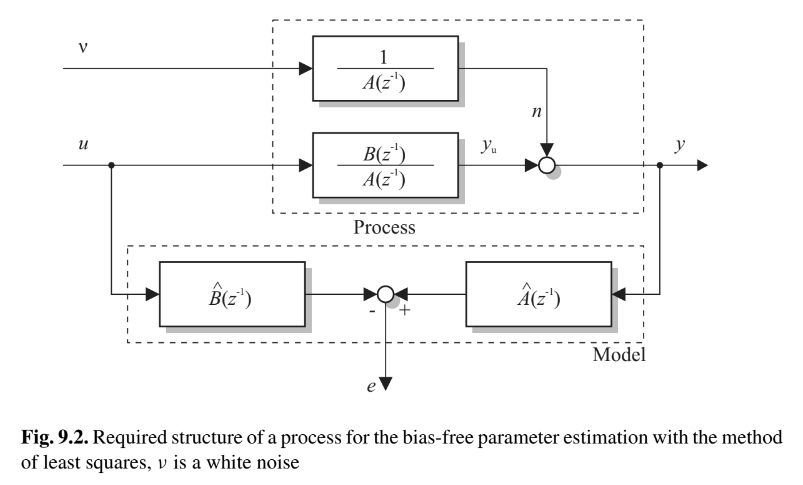

**Manejo de la incertidumbre en la estimación de los parámetros**

**Condiciones para la identificación del modelo**

**Método de mínimos cuadrados recursivo**

### Clase 8: Método de mínimos cuadrados (aplicaciones)

### Clase 9: Métodos de variable instrumental

### Clase 10: Métodos de variable instrumental

# Funciones adicionales para el curso

function funresult=ldiv(a,b,N)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Function (ldiv) : calculate inverse Z-transform by long division 
% Author : Tamer mohamed samy abdelazim Mellik
% Contact information : 
%Department of Electrical & Computer Engineering,
%University of Calgary,
%2500 University Drive N.W. ,
%Calgary, AB T2N 1N4 ,
%Canada .
% email :abdelasi@enel.ucalgary.ca  
% email : tabdelaz@ucalgary.ca
% Webpage : http://www.enel.ucalgary.ca/~abdelasi/
% Date    : 2-5-2002
% Version : 1.0.0
%Example
% This function like deconv but it help if the numerator less or equal degree of denominator
% if you have this function (It must arranged in terms of minus power of Z):
%              1
% G(z)= -----------------      
%             -1     -2
%      ( 5 - Z  - 3 Z  )
% and you want to calculate long division or inverse Z transform :
% The numerator  is a=[1] and  the denominator is b= [5 -1 -3 ]
% call the function ldiv(a,b) to get the funresult 20 items (default)
% another example :
%                -2     -3 
%       ( 5 - 3 Z  + 4 Z  )
%  G(z)-----------------      
%              -1     -2
%        (5 - Z  - 3 Z )
% a=[5 0 -3 4] , b= [5 -1 -3 ] and you want the funresult 100 terms !
% ldiv(a,b,100) 
% Note : The author doesn't have any responsibility for any harm caused by the use of this file
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%a numerator
%b denominator
%default order of the filter == 20
funresult=[];
if nargin < 3
    if nargin > 1
            N=20;
    else
            disp('Usage: M = ldiv(a,b,N)')
            disp('a:numerator , b denominator and N is the order of the resultant filter')
            return
    end 
end
if size(a) < 1
    disp('Error: numerator must at least have one element not empty')
    return
end
if size(b) < 1
    disp('Error: denominator must at least have one element not empty')
    return
end
if b(1)==0
    disp('Error: The first element of denominator must have nonzero value')
    return
end
if size(b) < 2
    funresult=a./b;
    for i =length(funresult)+1:N
       funresult(i)=0;
    end
    return
end
for i = length(a)+1:N
    a(i)=0;
end
for i = 1 : N
    funresult(i)=a(1)/b(1);
    if length(a)>1
            for k= 2:length(b)
                if k > length(a)
                    a(k)=0;
                end
                a(k)=a(k)-funresult(length(funresult))*b(k);
            end
        for i = 1:length(a)-1
                a(i)=a(i+1);
        end
        a=a(1:length(a)-1);
    end
end
end